clc;clear variables;
define_constants;
% system_type='sqr60';%or use 'admin', indicating that we will use the urban boundary to generate the required data
[~,~,raw_cities]=xlsread('E:\Code\For_Research\City_data\city_basic_data.xlsx');
[~,~,country_road_speed]=xlsread('E:\code\CICR_toolbox\transportation network toolbox\country_road_speed.xlsx');
system_type_all = ['sqr10';'sqr20';'sqr30';'sqr40';'sqr50';'sqr60';'admin'];
city_set = [3	8	13	20	22	26	38	41	43	46	48	50	51	53	56	61	72	73	77	79	95	97	98	100	101	104	110	111	118	119 ...
            122	123	127	128	129	137	144	149	151	152	153	154	155	156	157	158	159	160	161	162	163	164	165	166	167	168	169	170	171	172	... 
            173	174	175	176	177	178	179	180	181	182	183	184	185	186	187	188	189	190	191	192	193	194	195	196	197	198	199	200	201	202	... 
            203	204	205	206	207	208	209	210	211	212];
% city_set = [3	8	13	20	22	26	38	41	43	46	48	50	51	53	56	61	72	73	77	79	95	97	98	100	101	104	110	111	118	119 ...
%             122	123	127	128	129	137	144	151	152	153	154	155	156	157	158	159	160	161	162	163	164	165	166	167	168	169	170	171	172	... 
%             173	175	176	177	178	179	180	181	182	183	184	185	186	187	188	189	190	191	192	193	194	195	196	197	198	199	200	201	202	... 
%             203	204	205	206	207	208	209	210	211	212];
% city_set = [149];
spearman_corr=zeros(length(city_set),7);
a=zeros(length(city_set),7);
b=zeros(length(city_set),7);
c=zeros(length(city_set),7);
%% load  data
for city_i=1:length(city_set)
     city_id = city_set(city_i);

    for type_i = 1:7
    system_type = system_type_all(type_i,:);
    %% 
    bd_path = strcat('E:\Code\For_Research\City_data\',system_type,'_city_road_network\');
    ps_result_path = strcat('E:\Code\For_Research\Result\path structure\',system_type,'_city_road_network\');   
    %% main codes to generate the required data from osmnx
       
            city_name=cell2mat(raw_cities(city_id,CN));%city name
            clog=cell2mat(raw_cities(city_id,CX));
            clat=cell2mat(raw_cities(city_id,CY));
            country_id=42;%cell2mat(raw_cities(city_id,13));
            if type_i<=5
                load(strcat(bd_path,num2str(city_id),city_name,'\',system_type,'_node_data'),'local_node_data');node_data=local_node_data;N=size(node_data,1);
                load(strcat(bd_path,num2str(city_id),city_name,'\',system_type,'_edge_data'),'local_edge_data');edge_data=local_edge_data;E=size(edge_data,1);
                else
                load(strcat(bd_path,num2str(city_id),city_name,'\',system_type,'_node_data'),'node_data');N=size(node_data,1); 
                load(strcat(bd_path,num2str(city_id),city_name,'\',system_type,'_edge_data'),'edge_data');E=size(edge_data,1);
            end
            load(strcat(ps_result_path,num2str(city_id),city_name,'\',system_type,'_net_psm'),'net_psm');
            load(strcat(ps_result_path,num2str(city_id),city_name,'\',system_type,'_com_psm'),'com_psm'); 
            
            if type_i==1
                Bn_sqr10=com_psm.ft_Bn;
                node_sqr10_xy=node_data(:,2:3);
            else
                Bn_else=com_psm.ft_Bn;
                node_sqr_else_xy=node_data(:,2:3);
            end
   %匹配节点
            if type_i>=2 

                try
                    [~,row_sqr_else,row_sqr10] = intersect(node_sqr_else_xy,node_sqr10_xy,'rows') ; %检索其他区域节点在该10*10区域内的序号row_else，以及相对应的10*10区域原本序号if length(row_sqr10)/length(node_sqr10_xy) < 0.99  %如果精确匹配误差太大，用近似匹配        
                    if length(row_sqr10)/length(node_sqr10_xy) < 0.99  %如果精确匹配误差太大，用近似匹配
                        [row_sqr_else,row_sqr10] = node_matching(node_sqr_else_xy,node_sqr10_xy) ;
                    end
                catch
                    %如果精确匹配报错，也使用近似匹配
                    [row_sqr_else,row_sqr10] = node_matching(node_sqr_else_xy,node_sqr10_xy) ;
                end
       

匹配10公里范围内的节点，计算中心区域的节点数量比例

                a(city_i,type_i)=length(row_sqr10);%其他边界在sqr10下匹配的点的数量
                b(city_i,type_i)=length(node_sqr_else_xy);%其他节点数量
                c(city_i,type_i)=a(city_i,type_i)/b(city_i,type_i);

相应的，计算其他边界在中心区域的节点重要度（介数）结果与中心区域结果的差异

                Bn_match_sqr10=Bn_sqr10(row_sqr10);%这些节点在其他区域下计算的介数
                Bn_match_insqr10=Bn_else(row_sqr_else);%这些节点在该区域下计算出的介数
                
                [~,index_sqr10] = sort(Bn_match_sqr10,"descend");
                Bn_rank_sqr10 = zeros(size(index_sqr10));
                Bn_rank_sqr10(index_sqr10) = (1:length(index_sqr10))';%算
                
                [~,index_else] = sort(Bn_match_insqr10,"descend");
                Bn_rank_else = zeros(size(index_else));
                Bn_rank_else(index_else) = (1:length(index_else))'; %算其他区域得到的介数的排名
                [RHO,PVAL] = corr(Bn_rank_sqr10,Bn_rank_else,'Type', 'Spearman'); %spearman相关系数  
                spearman_corr(city_i,type_i)=RHO; 
            end          
    end
end
c(:,1)=1;
spearman_corr(:,1)=1;


作图，图一是节点的占比图

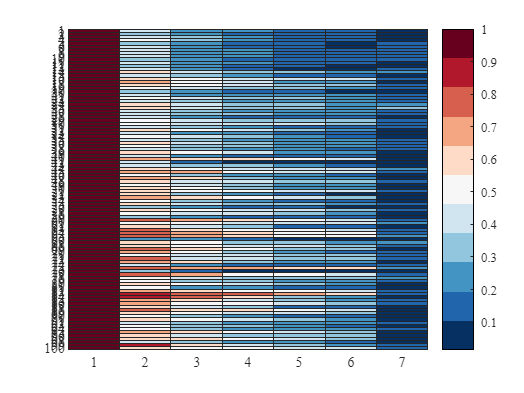

figure;
h1=heatmap(c);
h1.CellLabelFormat = '%0.3f';  %展示精度
% colormap(gca, 'parula')     %改颜色
colormap(redbluecmap);
set(gca,'FontName','Times New Roman','FontSize',7);

% sorty(h1); 

作图，图二是相关系数

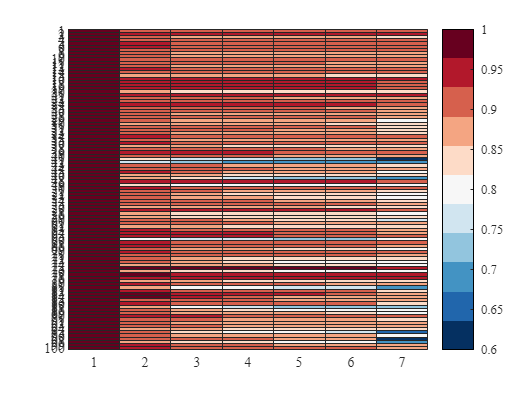

% spearman_corr_city=[city_set',spearman_corr];
% 
% xname={};
% yname={'sqr20','sqr30','sqr40','sqr50','sqr60','admin'}
figure;
h2=heatmap(spearman_corr);
h2.CellLabelFormat = '%0.3f';  %展示精度
% colormap(gca, 'parula')     %改颜色

colormap(redbluecmap);
set(gca,'FontName','Times New Roman','FontSize',7);

% sorty(h2); 

接下来分析两者的联系，想法是获得同一边界下，两组数据的排名，再来看排名的的作图

corr_node_ratio_between=zeros(1,7); %节点占比和介数的相关系数
for type_i=2:7
    [~,I1]=sort(c(:,type_i),'descend'); %返回节点占比排名
    [~,I2]=sort(spearman_corr(:,type_i),'descend'); %返回介数排名
    [RHO,PVAL] = corr(I1,I2,'Type', 'Spearman'); %spearman相关系数  
    corr_node_ratio_between(type_i)=RHO 
end

corr_node_ratio_between =          0   -0.0292         0         0         0         0         0


corr_node_ratio_between =          0   -0.0292   -0.0935         0         0         0         0


corr_node_ratio_between =          0   -0.0292   -0.0935   -0.0458         0         0         0


corr_node_ratio_between =          0   -0.0292   -0.0935   -0.0458   -0.1833         0         0


corr_node_ratio_between =          0   -0.0292   -0.0935   -0.0458   -0.1833   -0.0345         0


corr_node_ratio_between =          0   -0.0292   -0.0935   -0.0458   -0.1833   -0.0345    0.0872


相关系数不行，那就直接根据排名作图

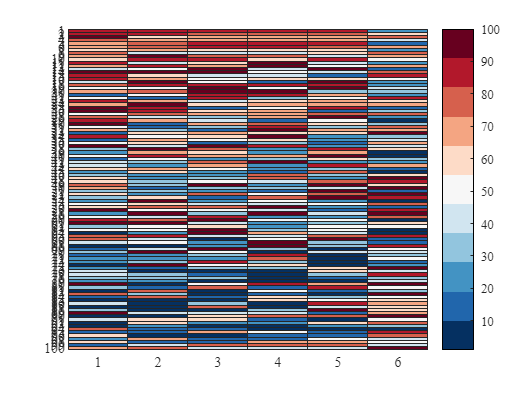

rank_node_ratio=zeros(100,7);
rank_bc_spearman=zeros(100,7);
for type_i=2:7
    
    [~,rank_node_ratio(:,type_i)]=sort(c(:,type_i),'descend'); %返回节点占比排名
    [~,rank_bc_spearman(:,type_i)]=sort(spearman_corr(:,type_i),'descend'); %返回介数相关性排名
  
end
%画出
figure;
h3=heatmap(rank_node_ratio(:,2:7));
h3.CellLabelFormat = '%0.3f';  %展示精度
% colormap(gca, 'parula')     %改颜色
colormap(redbluecmap);
set(gca,'FontName','Times New Roman','FontSize',7);

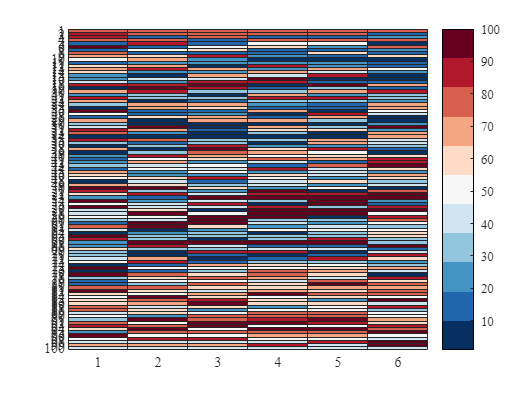

% sorty(h2); 
figure;
h4=heatmap(rank_bc_spearman(:,2:7));
h4.CellLabelFormat = '%0.3f';  %展示精度
% colormap(gca, 'parula')     %改颜色
colormap(redbluecmap);
set(gca,'FontName','Times New Roman','FontSize',7);

这里有几个想法，

一是做出类似于下面的连线图（来源From the betweenness）,先以sqr50为例

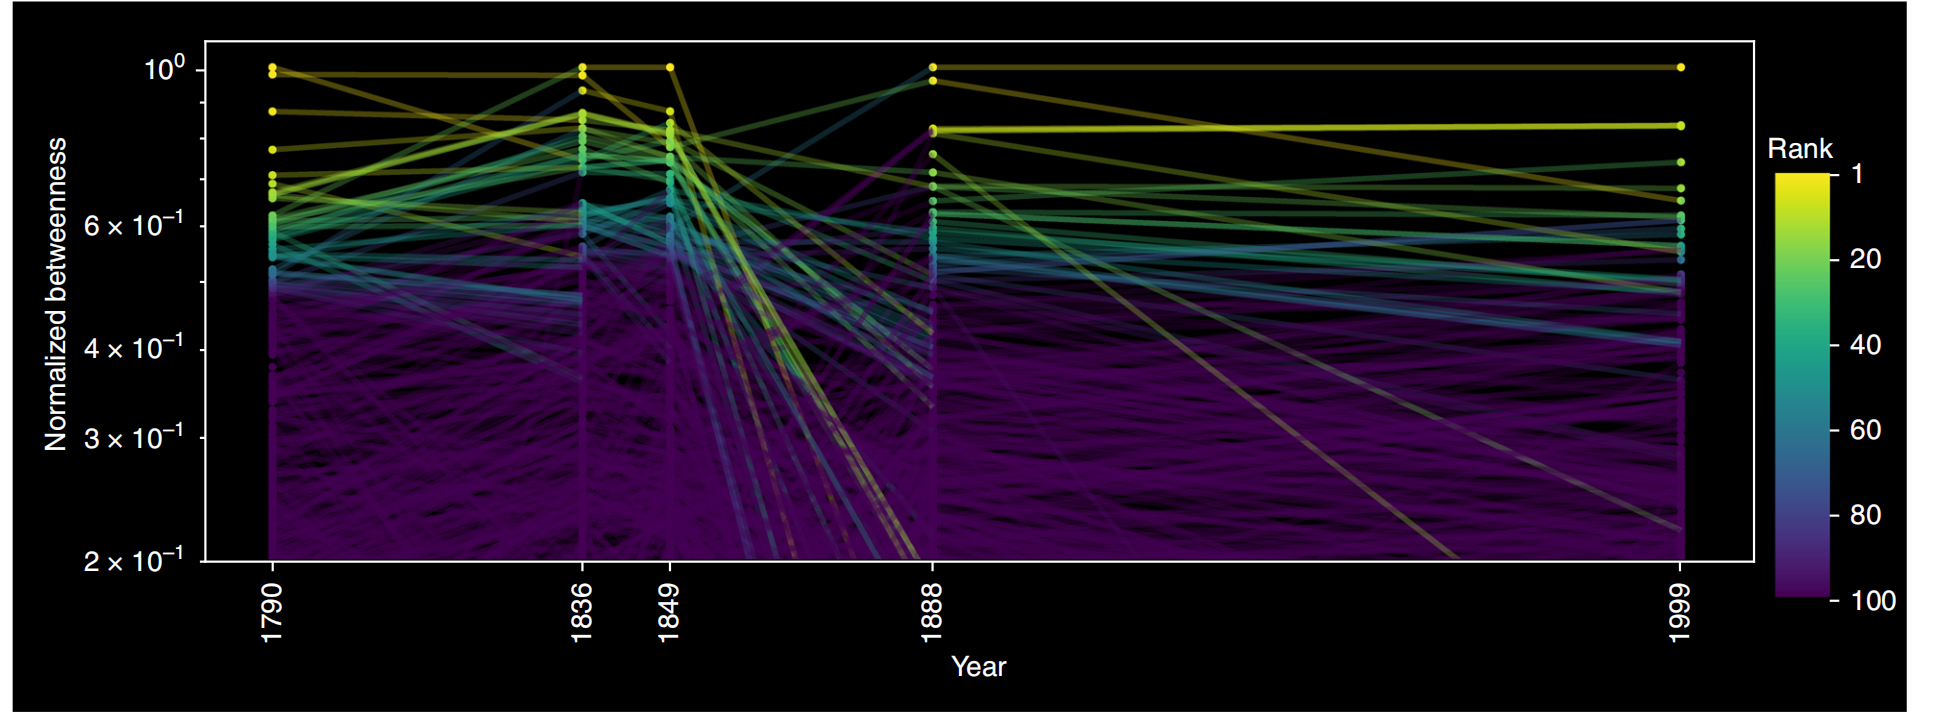

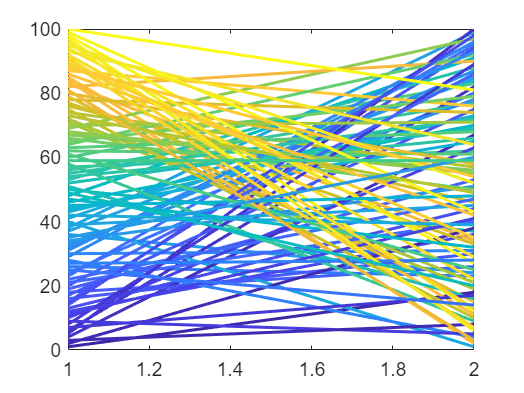

figure;
color_value=[parula(64) linspace(1,100,64)' linspace(0,1,64)'];
% color_value=[cool(64) linspace(-1,1,64)' linspace(0,1,64)'];
X1=ones(100,1);
Y1=101-rank_node_ratio(:,5);
% point_set_1 = [X1,Y1];

X2=ones(100,1)*2;
Y2=101-rank_bc_spearman(:,5);
% point_set_2 = [X2,Y2];

for i=1:100
   temp_cv=sortrows([color_value(:,1:3) abs(color_value(:,4)- Y1(i))],4);
   h=plot([X1(i),X2(i)],[Y1(i),Y2(i)],'color',temp_cv(1,1:3),'LineWidth',1.5); hold on;
end

再来测试下sqr60的

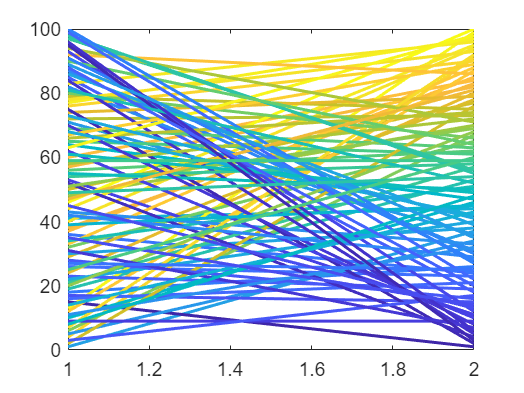

figure;
color_value=[parula(64) linspace(1,100,64)' linspace(0,1,64)'];
% color_value=[cool(64) linspace(-1,1,64)' linspace(0,1,64)'];
X1=ones(100,1);
Y1=101-rank_node_ratio(:,6);
% point_set_1 = [X1,Y1];

X2=ones(100,1)*2;
Y2=101-rank_bc_spearman(:,6);
% point_set_2 = [X2,Y2];

for i=1:100
   temp_cv=sortrows([color_value(:,1:3) abs(color_value(:,4)- Y2(i))],4);
   h=plot([X1(i),X2(i)],[Y1(i),Y2(i)],'color',temp_cv(1,1:3),'LineWidth',1.5); hold on;
end

发现效果不是很好，但是这种图或许可以用在城市spearman系数排名随边界扩大的变化

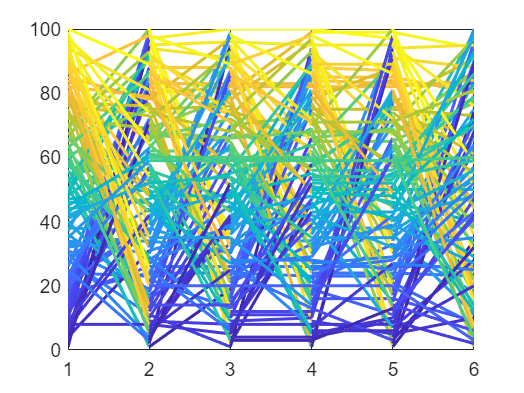

figure;
color_value=[parula(64) linspace(1,100,64)' linspace(0,1,64)'];
% color_value=[cool(64) linspace(-1,1,64)' linspace(0,1,64)'];
X1=ones(100,1);
Y1=101-rank_node_ratio(:,2);
% point_set_1 = [X1,Y1];

X2=ones(100,1)*2;
Y2=101-rank_bc_spearman(:,3);
% point_set_2 = [X2,Y2];

X3=ones(100,1)*3;
Y3=101-rank_bc_spearman(:,4);

X4=ones(100,1)*4;
Y4=101-rank_bc_spearman(:,5);

X5=ones(100,1)*5;
Y5=101-rank_bc_spearman(:,6);

X6=ones(100,1)*6;
Y6=101-rank_bc_spearman(:,7);

for i=1:100
   temp_cv=sortrows([color_value(:,1:3) abs(color_value(:,4)- Y1(i))],4);
   plot([X1(i),X2(i)],[Y1(i),Y2(i)],'color',temp_cv(1,1:3),'LineWidth',1.5); hold on;
   temp_cv=sortrows([color_value(:,1:3) abs(color_value(:,4)- Y2(i))],4);
   plot([X2(i),X3(i)],[Y2(i),Y3(i)],'color',temp_cv(1,1:3),'LineWidth',1.5); hold on;
   temp_cv=sortrows([color_value(:,1:3) abs(color_value(:,4)- Y3(i))],4);
   plot([X3(i),X4(i)],[Y3(i),Y4(i)],'color',temp_cv(1,1:3),'LineWidth',1.5); hold on;
   temp_cv=sortrows([color_value(:,1:3) abs(color_value(:,4)- Y4(i))],4);
   plot([X4(i),X5(i)],[Y4(i),Y5(i)],'color',temp_cv(1,1:3),'LineWidth',1.5); hold on;
   temp_cv=sortrows([color_value(:,1:3) abs(color_value(:,4)- Y5(i))],4);
   plot([X5(i),X6(i)],[Y5(i),Y6(i)],'color',temp_cv(1,1:3),'LineWidth',1.5); hold on;
end

二是根据值画四象限图，来进行分类

% figure;


或许，用相关系数的排名

三是只根据相关系数对城市进行分类